# **HW - separate audio mix using ICA**

Load mixed audio (save sample audio into ../data directory)

In this assignment, the number of audio sources is equal to mic (channels)

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.10 available
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit) - new version 5.5 available
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


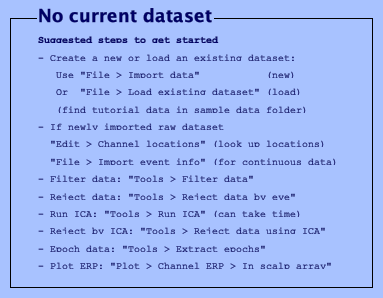

eeglab;

### Goals

- To estimate original audio soures through ICA

- To estimate mixing matrix wegiths (N by N matrix)

- To select corresponding sources that consists of the given audio mix and justify it (based on minimum error, highest correlation, comparing their spectrogram, etc.)

[X, fs] = audioread('../data/mixed_audio_2mix_v2.wav');  % X: (samples x channels)

disp('Mixed audio dimension:');

Mixed audio dimension:


disp(size(X));

    10625664           2



### Play the given audio mix

player = audioplayer(X, fs);
play(player)

### Stop playing    

stop(player)

## Transpose to (channels x samples)

X = X';  % Transpose to (channels x samples)

## Run ICA runica() in EEGLAB (it could be slow)

% ================= Your code =========================

ica = [];
[ica.weights, ica.sphere] = runica(X);


Input data size [2,10625664] = 2 channels, 10625664 frames/nFinding 2 ICA components using logistic ICA.
Decomposing 2656416 frames per ICA weight ((4)^2 = 10625664 weights, Initial learning rate will be 0.000937752, block size 81.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.999985 to 0.999985
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ...
step 1 - lrate 0.000938, wchange 0.24687728, angledelta  0.0 deg
step 2 - lrate 0.000938, wchange 0.00755568, angledelta  0.0 deg
step 3 - lrate 0.000938, wchange 0.00415356, angledelta 77.3 deg
step 4 - lrate 0.000844, wchange 0.00165535, angledelta 43.8 deg
step 5 - lrate 0.000844, wchange 0.00193124, angledelta 69.3 deg
step 6

### Normalize estimated sources

Your estimated souces should be [Nch x samples]

When your estimated sources are Xhat, normalization could be following:

% ================ Your code (refer to the lecture material)
% X_hat = icaweights * icasphere * X;

X_hat = ica.weights * ica.sphere * X;

% Normalization
X_hat = X_hat ./ max(abs(X_hat), [], 2);

### Play estimated source 1

player_estimated1 = audioplayer(X_hat(1, :), fs);
play(player_estimated1);

### Stop estimated source 1

stop(player_estimated1);

### Play estimated source 2

player_estimated2 = audioplayer(X_hat(2, :), fs);
play(player_estimated2);

### Stop estimated source 2

stop(player_estimated2);

### Your code - compare your estimated sources to the original sources and select which original sources were used to make the given audio mix

- Original sources can be downloaded in e-learning website

- Play and load each original sources

- Compare each original source to your estimated sources

- Answer two audio sources that consists of the given audio mix

- Demonstrate how similar your estimated sources and original sources through various methods (if data vector is too long, you can crop a part of data)

#### Load original source

audio_dir = '../data/example_sound_sources/'; % 교수님께서 공유해주신 example sounds directory 명시
files = dir(fullfile(audio_dir, '*.wav')); % 모든 *.wav file 찾기

min_len = inf;
fs_all = zeros(length(files),1); 
S = [];
for i = 1:length(files) 
    [y, fs] = audioread(fullfile(audio_dir, files(i).name));
    y = y(:,1);  % mono 변환
    fs_all(i)=fs;
    min_len = min(min_len, length(y));
    S = [S; y'];  % 가로로 이어붙임 (후에 자름)
end

% 샘플링 레이트 통일 확인
if ~all(fs_all == fs_all(1))
    error('All audio files must have the same sampling rate');
end
fs = fs_all(1);

disp('Dimension of original source list'); 

Dimension of original source list


disp(size(S)); % 총 11개의 original source

          11    10625664



### Downsampling for comparison - original source is too big to conduct correlation or visualization

down_xhat = resample(X_hat', 1, 48)'; % down_xhat(1, :): Esimation 1, down_xhat(2, :): Esimation 2
down_S = resample(S', 1, 48)'; % 교수님께서 공유해주신 original source

#### Compare source 1 vs. original sources 

- (based on minimum error, highest correlation, comparing their spectrogram, etc.)

% ============================= your code
% Above image is instructor's example. You don't need to exactly replicate
% this example. It is not related to the current assignment - source 7 and
% 3 are not the answer of the current assignment.

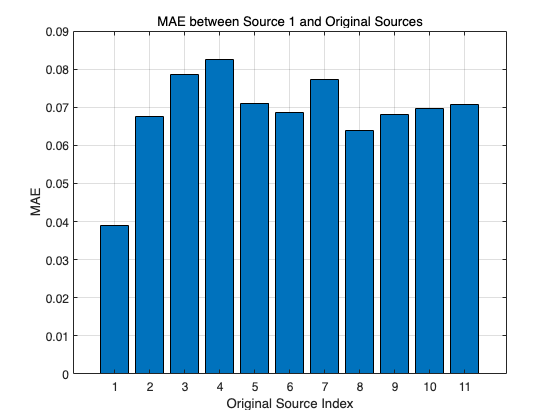

% exp1: based on minimum error (MAE)

mae_values1 = zeros(1, size(down_S, 1));
for i = 1:size(down_S, 1)
    mae_values1(i) = mean(abs(down_xhat(1, :) - down_S(i, :)));
end

figure;
bar(mae_values1);
title('MAE between Source 1 and Original Sources');
xlabel('Original Source Index');
ylabel('MAE');
grid on;

original source 1의 MAE가 가장 작음 -> estimation 1은 source 1일 것이다.

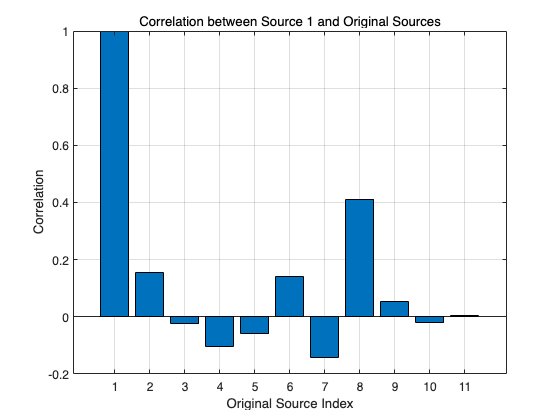

% exp2: based on highest correlation

corr_values1 = zeros(1, size(down_S, 1));
for i = 1:size(down_S, 1)
    corr_values1(i) = corr(down_xhat(1, :)', down_S(i, :)');
end

figure;
bar(corr_values1);
title('Correlation between Source 1 and Original Sources');
xlabel('Original Source Index');
ylabel('Correlation');
grid on;

�original source 1과의 correlation이 가장 큼 -> estimation 1�은 source 1일 것이다.

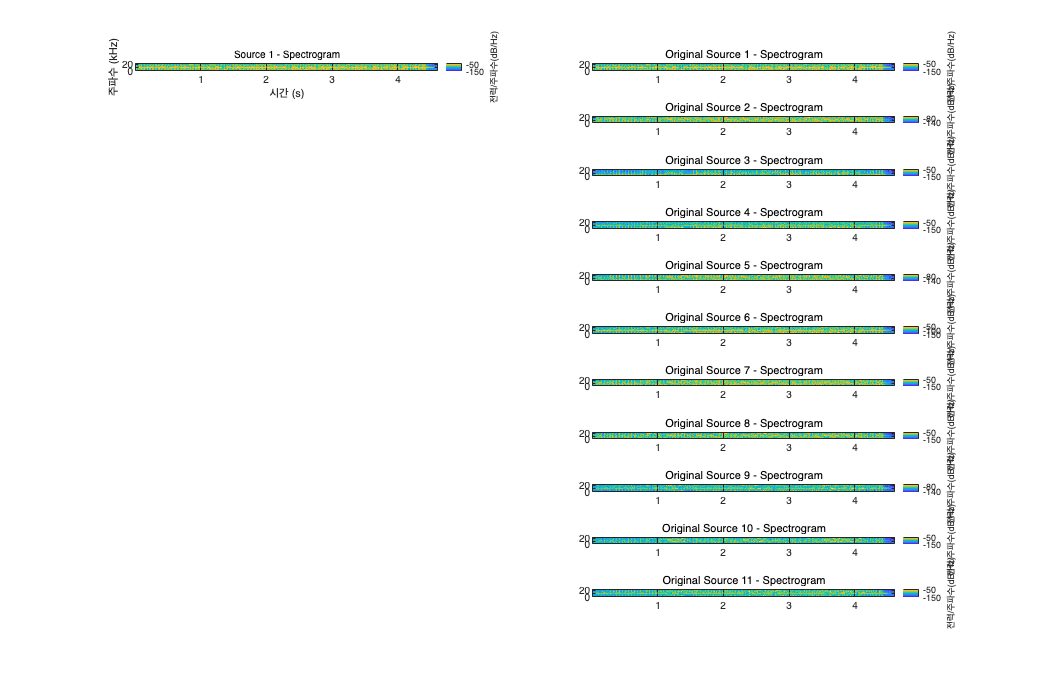

% exp3: based on spectrogram

figure;

% Source 1 (1개)
subplot(size(down_S, 1), 2, 1);
spectrogram(down_xhat(1, :), 256, 200, 256, fs, 'yaxis');
title('Source 1 - Spectrogram', 'FontSize', 10);  % 제목에 폰트 크기 설정

% Original Source 11개
for i = 1:size(down_S, 1)
    subplot(size(down_S, 1), 2, 2 * i);
    spectrogram(down_S(i, :), 256, 200, 256, fs, 'yaxis');
    title(sprintf('Original Source %d - Spectrogram', i), 'FontSize', 11);
    xlabel(''); ylabel('');
end

set(gcf, 'Position', [100, 100, 1200, 800]);

Source 1�과 original source 1의 spectogram이 가장 유사함

#### Compare source 2 vs. original sources (based on minimum error, highest correlation, comparing their spectrogram, etc.)

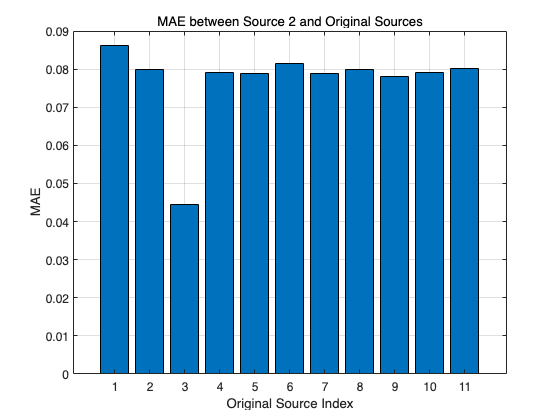

% ============================ your code
% Above image is instructor's example. You don't need to exactly replicate
% this example. It is not related to the current assignment - source 7 and
% 3 are not the answer of the current assignment.
% exp1: based on minimum error (MAE)

mae_values2 = zeros(1, size(down_S, 1));
for i = 1:size(down_S, 1)
    mae_values2(i) = mean(abs(down_xhat(2, :) - down_S(i, :)));  % Source 2와 비교
end

figure;
bar(mae_values2);
title('MAE between Source 2 and Original Sources');
xlabel('Original Source Index');
ylabel('MAE');
grid on;

original source 3의 MAE가 가장 작음 -> estimation 2은 source 3일 것이다.

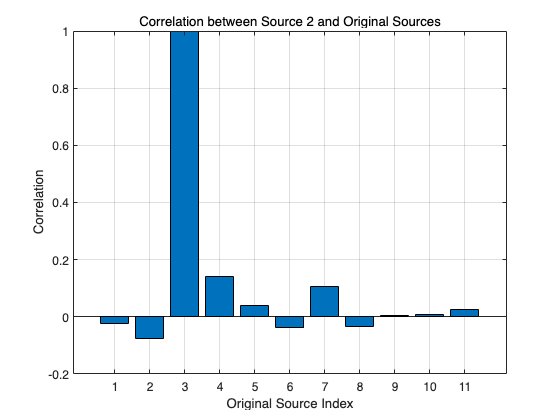

% exp2: based on highest correlation

corr_values2 = zeros(1, size(down_S, 1));
for i = 1:size(down_S, 1)
    corr_values2(i) = corr(down_xhat(2, :)', down_S(i, :)');
end

figure;
bar(corr_values2);
title('Correlation between Source 2 and Original Sources');
xlabel('Original Source Index');
ylabel('Correlation');
grid on;

original source 3과의 correlation이 가장 큼 -> estimation 2�은 source 3일 것이다.

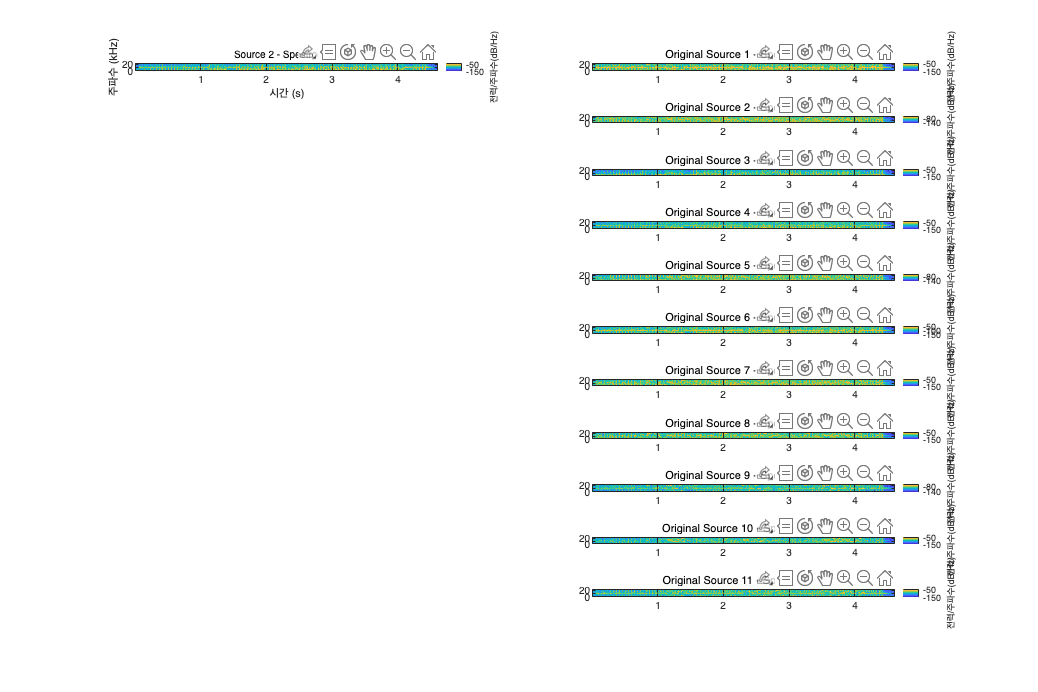

% exp3: based on spectrogram

figure;

% Source 2 (1개)
subplot(size(down_S, 1), 2, 1);
spectrogram(down_xhat(2, :), 256, 200, 256, fs, 'yaxis');
title('Source 2 - Spectrogram', 'FontSize', 10);

% Original Source 11개
for i = 1:size(down_S, 1)
    subplot(size(down_S, 1), 2, 2 * i);
    spectrogram(down_S(i, :), 256, 200, 256, fs, 'yaxis');
    title(sprintf('Original Source %d - Spectrogram', i), 'FontSize', 11);
    xlabel(''); ylabel('');
end

set(gcf, 'Position', [100, 100, 1200, 800]);

Source 2�과 original source 3의 spectogram이 가장 유사함

## Export & submission

Export your estimated sources and upload to e-learning page

- Format: *.wav

- Matlab live scripts or Python scripts

### Notes

- ICA does not care order, magnitude, so estimated mixing matrix and original mixing matrix could look different.

% Check if X_hat is [n_sample x n_ch]

for i=1:size(X_hat, 1)
    fname = sprintf('../data/estimated_source%02d.wav', i);
    audiowrite(fname, X_hat(i, :)', fs);
end